# Taller 1: Perceptrón y Adaline

**Asignatura:** Inteligencia Computacional Aplicada

**Docente:** Cesar Andrey Perdomo Charry

**Estudiante:** Sergio Santiago Duarte Rojas

clear; clc; close all;

## =========================================================================

## PARTE A — EL PERCEPTRÓN SIMPLE

## =========================================================================

## 1. Fundamento teórico: el Perceptrón Simple (Rosenblatt, 1958)

El **Perceptrón Simple** es el modelo neuronal artificial más antiguo con capacidad de **aprendizaje**. Una sola neurona calcula una suma ponderada de sus entradas (incluyendo un sesgo, representado como una entrada constante igual a 1) y aplica una **función escalón** (umbral):


$$net = \sum_{i=1}^{n} w_i x_i + w_0, \qquad Y(x) = \begin{cases} 1 & \text{si
 } net \geq \theta \\ 0 & \text{si } net < \theta \end{cases}$$


donde $\theta$ es el umbral de activación (parametrizable en este taller).

**Tres reglas de ajuste de pesos**

Este taller le pide dejar el modelo parametrizable para elegir entre tres formas de corregir los pesos ante cada patrón:


$$\text{(1) } \Delta w_i = d(x)\, x_i \qquad \text{(regla tipo Hebbiana, no
 usa la salida actual de la red)}$$



$$\text{(2) } \Delta w_i = \left[d(x) - Y(x)\right] x_i \qquad \text{(Regla
 de Aprendizaje del Perceptrón, Rosenblatt 1958)}$$



$$\text{(3) } \Delta w_i = \alpha \left[d(x) - Y(x)\right] x_i \qquad \text{(regla
 (2) con tasa de aprendizaje } \alpha \text{)}$$


En los tres casos, el ajuste final es $w_i^{*} = w_i + \Delta w_i$.

La regla (2)/(3) es la más importante desde el punto de vista teórico: el **Teorema de Convergencia del Perceptrón** garantiza que, si los datos son **linealmente separables**, el algoritmo encuentra un hiperplano separador en un número finito de iteraciones. Las compuertas AND y OR son linealmente separables (por eso este taller las usa para validar el modelo); el problema XOR **no** lo es — este límite motiva la red multicapa del Taller 2.

**Referencias y lecturas complementarias**

- Rosenblatt, F. (1958). The perceptron: A probabilistic model for information storage and organization in the brain. *Psychological Review*, 65(6), 386-408.  [doi.org/10.1037/h0042519](https://doi.org/10.1037/h0042519)

- Novikoff, A. B. (1962). On convergence proofs for perceptrons.  *Proceedings of the Symposium on the Mathematical Theory of Automata*, 12, 615-622. (demostración formal del teorema de convergencia)

- Minsky, M., & Papert, S. (1969). *Perceptrons: An Introduction to Computational Geometry*. MIT Press. (limitaciones del Perceptrón simple, incluyendo XOR)

- Haykin, S. (2009). *Neural Networks and Learning Machines* (3rd ed.), Capítulo 1: Rosenblatt's Perceptron. Pearson.

- MathWorks. [Perceptron Neural Networks](https://www.mathworks.com/help/deeplearning/ug/perceptron-neural-networks.html)

## 2. Parámetros del modelo (totalmente parametrizable)

**Qué se espera en esta sección:** una estructura `cfg` editable que controla el número de entradas, el umbral de activación, la regla de aprendizaje y la tasa $\alpha$.

**Dónde modificar:** cambie `cfg.learning_rule` entre `'hebb'`, `'perceptron'` y `'perceptron_alpha'` para comparar las tres reglas (numeral 3 del taller), y `cfg.n_inputs` para probar compuertas de 2, 3 y 4 entradas.

cfg.n_inputs      = 2;
cfg.threshold     = 0.5;              % umbral theta de la función escalón
cfg.learning_rule = 'perceptron_alpha'; % 'hebb' | 'perceptron' | 'perceptron_alpha'
cfg.alpha         = 0.1;              % solo se usa si learning_rule = 'perceptron_alpha'
cfg.max_epochs    = 100;
cfg.seed          = 1;
cfg.init_scale    = 0.5;              % escala de los pesos iniciales, W = randn * init_scale
cfg.n_seeds       = 10;               % repeticiones con distinta semilla en los reportes
cfg.normalize     = true;             % escalado min-max de las entradas en datos reales

rng(cfg.seed);

## 3. Generación de datos: compuertas lógicas AND / OR

**Teoría:** las compuertas AND y OR de $n$ entradas tienen $2^n$ combinaciones posibles. AND es 1 solo cuando **todas** las entradas son 1; OR es 1 cuando **al menos una** entrada es 1. Ambas son linealmente separables para cualquier $n$, por lo que el Perceptrón simple debe poder aprenderlas sin error.

**Qué se espera en esta sección:** la función devuelve la tabla de verdad completa como matriz de patrones `X` y vector de salidas deseadas `D`.

**Dónde modificar:** esta función ya está completa (es una utilidad de generación de datos, no el algoritmo de aprendizaje).

## 4. Inicialización del Perceptrón

**Teoría:** los pesos (incluido el sesgo) se inicializan con valores aleatorios pequeños; a diferencia del MLP, en un modelo de una sola neurona la inicialización no es crítica para la convergencia (el Teorema de Convergencia garantiza que se alcanza una solución sin importar el punto de partida, siempre que los datos sean linealmente separables).

**Qué se espera en esta sección:** la función devuelve `W` (vector de pesos, tamaño `n_inputs`) y `b` (sesgo escalar).

## 5. Función de activación — Función Escalón

**Teoría:** la función escalón compara la suma ponderada `net` contra el umbral `threshold` y produce una salida binaria. Es la misma función para el Perceptrón y para la etapa final de decisión de Adaline (Parte B).

**Qué se espera en esta sección:** esta función ya está completa.

## 6. Entrenamiento del Perceptrón — las tres reglas de ajuste de pesos

**Qué se espera en esta sección:** la función `train_perceptron` debe recorrer los patrones por varias épocas, calcular la salida actual `Y(x)`, y ajustar `W` y `b` según la regla seleccionada en `cfg.learning_rule`. Al finalizar, el modelo debe clasificar correctamente el 100%% de los patrones de una compuerta AND/OR (dato linealmente separable).

## 7. Prueba del Perceptrón con compuertas AND / OR (2, 3 y 4 entradas)

**Qué se espera en esta sección:** para cada compuerta y cada número de entradas, el modelo debe converger a 0 errores en pocas épocas. Registre estos resultados (número de épocas hasta converger, pesos finales) para el reporte de aprendizaje pedido en el numeral 3 del taller, variando la regla de aprendizaje, $\alpha$ y el umbral.

gates = {'AND', 'OR'};
n_inputs_list = [2, 3, 4];

for g = 1:numel(gates)
    for n = n_inputs_list
        cfg.n_inputs = n;
        [X, D] = generate_gate_data(n, gates{g});

        [W, b, epochs_to_converge] = train_perceptron(X, D, cfg);

        Y = zeros(size(D));
        for p = 1:size(X, 1)
            net = W * X(p, :)' + b;
            Y(p) = step_activation(net, cfg.threshold);
        end
        accuracy = mean(Y == D) * 100;

        fprintf('Compuerta %s (%d entradas) | regla=%s | épocas=%d | exactitud=%.1f%%\n', ...
            gates{g}, n, cfg.learning_rule, epochs_to_converge, accuracy);
    end
end

Compuerta AND (2 entradas) | regla=perceptron_alpha | épocas=17 | exactitud=100.0%
Compuerta AND (3 entradas) | regla=perceptron_alpha | épocas=9 | exactitud=100.0%
Compuerta AND (4 entradas) | regla=perceptron_alpha | épocas=19 | exactitud=100.0%
Compuerta OR (2 entradas) | regla=perceptron_alpha | épocas=18 | exactitud=100.0%
Compuerta OR (3 entradas) | regla=perceptron_alpha | épocas=43 | exactitud=100.0%
Compuerta OR (4 entradas) | regla=perceptron_alpha | épocas=14 | exactitud=100.0%


## 7.1 Reporte de aprendizaje, las tres reglas en las seis compuertas

Cada configuración se repite con `cfg.n_seeds` semillas. Se reporta el promedio de épocas, el porcentaje de ejecuciones que convergieron dentro de `cfg.max_epochs` y la exactitud promedio de los pesos finales.

rules = {'hebb', 'perceptron', 'perceptron_alpha'};
etiquetas = {'AND 2', 'AND 3', 'AND 4', 'OR 2', 'OR 3', 'OR 4'};
R1 = table();
for r = 1:numel(rules)
    cfg.learning_rule = rules{r};
    for g = 1:numel(gates)
        for n = n_inputs_list
            cfg.n_inputs = n;
            [X, D] = generate_gate_data(n, gates{g});
            ep = zeros(cfg.n_seeds, 1);  acc = ep;
            for s = 1:cfg.n_seeds
                rng(s);
                [W, b, ep(s)] = train_perceptron(X, D, cfg);
                acc(s) = accuracy_of(X, D, W, b, cfg.threshold);
            end
            R1 = [R1; table(rules(r), gates(g), n, mean(ep), 100*mean(ep < cfg.max_epochs), mean(acc), ...
                  'VariableNames', {'Regla', 'Compuerta', 'Entradas', 'Epocas', 'Convergio', 'Exactitud'})];
        end
    end
end
R1

R1 = 18×6 table
           Regla            Compuerta    Entradas    Epocas    Convergio    Exactitud
    ____________________    _________    ________    ______    _________    _________

    {'hebb'            }     {'AND'}        2          100          0         67.5   
    {'hebb'            }     {'AND'}        3          100          0         62.5   
    {'hebb'            }     {'AND'}        4          100          0           75   
    {'hebb'            }     {'OR' }        2          3.2        100          100   
    {'hebb'            }     {'OR' }        3          3.3        100          100   
    {'hebb'            }     {'OR' }        4          3.6        100          100   
    {'perceptron'      }     {'AND'}        2          5.9        100          100   
    {'perceptron'      }     {'AND'}        3         12.1        100          100   
    {'perceptron'      }     {'AND'}        4         12.3        100          100   
    {'perceptron'      }     {'OR' } 

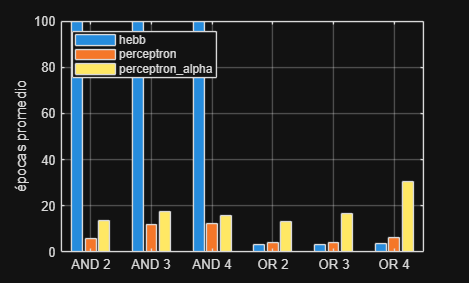


figure
bar(reshape(R1.Epocas, 6, 3))
set(gca, 'XTickLabel', etiquetas); ylabel('épocas promedio'); grid on
legend(rules, 'Interpreter', 'none', 'Location', 'northwest')

## 7.2 Efecto de la tasa de aprendizaje con la regla perceptron_alpha

cfg.learning_rule = 'perceptron_alpha';
alphas = [0.01 0.05 0.1 0.5 1];
E = zeros(6, numel(alphas));  k = 0;
for g = 1:numel(gates)
    for n = n_inputs_list
        k = k + 1;  cfg.n_inputs = n;
        [X, D] = generate_gate_data(n, gates{g});
        for a = 1:numel(alphas)
            cfg.alpha = alphas(a);
            ep = zeros(cfg.n_seeds, 1);
            for s = 1:cfg.n_seeds
                rng(s);  [~, ~, ep(s)] = train_perceptron(X, D, cfg);
            end
            E(k, a) = mean(ep);
        end
    end
end
R2 = array2table(E, 'RowNames', etiquetas, 'VariableNames', matlab.lang.makeValidName(compose('alpha %g', alphas)))

R2 = 6×5 table
             alpha0_01    alpha0_05    alpha0_1    alpha0_5    alpha1
             _________    _________    ________    ________    ______

    AND 2      71.3         24.2         13.7         7.4        5.9 
    AND 3      79.2           29         17.7        10.7       12.1 
    AND 4      80.1         24.7         15.6        14.8       12.3 
    OR 2       77.4         23.5           13         4.7          4 
    OR 3       75.2         30.9         16.8         5.7        4.3 
    OR 4       91.4           57         30.4         8.8        6.3 


## 7.3 Efecto del umbral de la función escalón

cfg.alpha = 0.1;
thresholds = [0 0.5 1];
E = zeros(6, numel(thresholds));  k = 0;
for g = 1:numel(gates)
    for n = n_inputs_list
        k = k + 1;  cfg.n_inputs = n;
        [X, D] = generate_gate_data(n, gates{g});
        for t = 1:numel(thresholds)
            cfg.threshold = thresholds(t);
            ep = zeros(cfg.n_seeds, 1);
            for s = 1:cfg.n_seeds
                rng(s);  [~, ~, ep(s)] = train_perceptron(X, D, cfg);
            end
            E(k, t) = mean(ep);
        end
    end
end
R3 = array2table(E, 'RowNames', etiquetas, 'VariableNames', matlab.lang.makeValidName(compose('umbral %g', thresholds)))

R3 = 6×3 table
             umbral0    umbral0_5    umbral1
             _______    _________    _______

    AND 2     15.4        13.7        14.7  
    AND 3     16.6        17.7        17.1  
    AND 4       12        15.6        13.2  
    OR 2      12.6          13        12.5  
    OR 3      19.9        16.8        19.5  
    OR 4      15.8        30.4          15  


## 7.4 Efecto de los pesos iniciales

Se cambia la escala de los pesos iniciales, desde exactamente cero hasta valores grandes frente a la corrección $\alpha$, y se mide cuánto tarda en converger y cuánto difieren los pesos finales entre semillas (rango entre el mayor y el menor valor final de cada peso).

cfg.threshold = 0.5;
init_scales = [0 1e-3 0.5 5];
R4 = table();
for g = 1:numel(gates)
    cfg.n_inputs = 2;
    [X, D] = generate_gate_data(2, gates{g});
    for sc = init_scales
        cfg.init_scale = sc;
        ep = zeros(cfg.n_seeds, 1);  Wf = zeros(cfg.n_seeds, 3);  acc = ep;
        for s = 1:cfg.n_seeds
            rng(s);
            [W, b, ep(s)] = train_perceptron(X, D, cfg);
            Wf(s, :) = [W b];  acc(s) = accuracy_of(X, D, W, b, cfg.threshold);
        end
        R4 = [R4; table(gates(g), sc, mean(ep), 100*mean(ep < cfg.max_epochs), mean(acc), max(Wf) - min(Wf), ...
              'VariableNames', {'Compuerta', 'Escala_inicial', 'Epocas', 'Convergio', 'Exactitud', 'Rango_W1_W2_b'})];
    end
end
cfg.init_scale = 0.5;
R4

R4 = 8×6 table
    Compuerta    Escala_inicial    Epocas    Convergio    Exactitud               Rango_W1_W2_b           
    _________    ______________    ______    _________    _________    ___________________________________

     {'AND'}             0             5        100          100               0            0            0
     {'AND'}         0.001             5        100          100       0.0036259    0.0042079     0.002977
     {'AND'}           0.5          13.7        100          100          1.0412      0.60443        1.211
     {'AND'}             5          44.2         90           95          10.314       10.639       10.335
     {'OR' }             0            12        100          100               0            0            0
     {'OR' }         0.001          12.7        100          100         0.10019     0.098877     0.002977
     {'OR' }           0.5            13        100          100          1.0476      0.60443      0.87341
     {'OR' }         

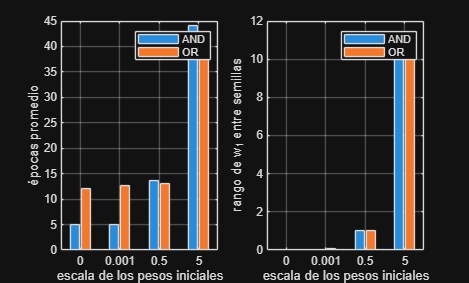


figure
subplot(1, 2, 1)
bar(reshape(R4.Epocas, 4, 2)); set(gca, 'XTickLabel', compose('%g', init_scales))
xlabel('escala de los pesos iniciales'); ylabel('épocas promedio'); grid on; legend(gates)
subplot(1, 2, 2)
bar(reshape(R4.Rango_W1_W2_b(:, 1), 4, 2)); set(gca, 'XTickLabel', compose('%g', init_scales))
xlabel('escala de los pesos iniciales'); ylabel('rango de w_1 entre semillas'); grid on; legend(gates)

## 7.5 Pesos finales según la regla de aprendizaje

Los pesos con que termina cada regla explican por qué hebb no resuelve la AND.

Pesos = table();
for r = 1:numel(rules)
    cfg.learning_rule = rules{r};
    for g = 1:numel(gates)
        cfg.n_inputs = 2;
        [X, D] = generate_gate_data(2, gates{g});
        rng(cfg.seed);
        [W, b, ep] = train_perceptron(X, D, cfg);
        Pesos = [Pesos; table(rules(r), gates(g), W(1), W(2), b, ep, accuracy_of(X, D, W, b, cfg.threshold), ...
              'VariableNames', {'Regla', 'Compuerta', 'W1', 'W2', 'b', 'Epocas', 'Exactitud'})];
    end
end
cfg.learning_rule = 'perceptron_alpha';
Pesos

Pesos = 6×7 table
           Regla            Compuerta      W1         W2          b        Epocas    Exactitud
    ____________________    _________    _______    _______    ________    ______    _________

    {'hebb'            }     {'AND'}      99.675     100.59     -99.379     100          75   
    {'hebb'            }     {'OR' }      7.6755     8.5906    -0.37923       4         100   
    {'perceptron'      }     {'AND'}      1.6755    0.59058     -1.3792       4         100   
    {'perceptron'      }     {'OR' }      1.6755     1.5906    -0.37923       5         100   
    {'perceptron_alpha'}     {'AND'}      1.1755    0.79058     -1.3792      17         100   
    {'perceptron_alpha'}     {'OR' }     0.97549    0.89058    -0.37923      18         100   


## 8. Partición de datasets — función `split_dataset`

**Teoría:** para evaluar el modelo sobre datos reales (numerales 4-6 del taller) se necesita separar un subconjunto de **entrenamiento** (usado para ajustar los pesos) de un subconjunto de **prueba** (usado solo para medir el desempeño, nunca para entrenar). Esto evita reportar una exactitud artificialmente optimista.

**Qué se espera en esta sección:** la función devuelve `Xtr`, `Dtr` (entrenamiento) y `Xte`, `Dte` (prueba), respetando la proporción indicada (p. ej. 0.7 para una partición 70-30).

## 9. Aplicación a datos reales — `data_banknote_authentication.txt`

**Qué se espera en esta sección:** cargar el dataset, generar las particiones 60-40, 70-30, 80-20 y 90-10 con `split_dataset`, entrenar un Perceptrón sobre cada una y comparar la exactitud de prueba, tal como pide el numeral 4-6 del taller (puede variar también $\alpha$ entre corridas, como sugiere el ejemplo del enunciado).

data = readmatrix('data_banknote_authentication.txt');
X_bank = data(:, 1:end-1);
D_bank = data(:, end);

vars_bank = {'varianza', 'asimetria', 'curtosis', 'entropia'};
Descriptivos = array2table([min(X_bank); max(X_bank); mean(X_bank); std(X_bank)]', ...
    'RowNames', vars_bank, 'VariableNames', {'Minimo', 'Maximo', 'Media', 'Desviacion'})

Descriptivos = 4×4 table
                 Minimo     Maximo     Media     Desviacion
                 _______    ______    _______    __________

    varianza     -7.0421    6.8248    0.43374      2.8428  
    asimetria    -13.773    12.952     1.9224       5.869  
    curtosis     -5.2861    17.927     1.3976        4.31  
    entropia     -8.5482    2.4495    -1.1917       2.101  


Clases = table(sum(D_bank == 0), sum(D_bank == 1), size(X_bank, 1), ...
    'VariableNames', {'Clase_0', 'Clase_1', 'Total'})

Clases = 1×3 table
    Clase_0    Clase_1    Total
    _______    _______    _____

      762        610      1372 



proporciones = [0.6, 0.7, 0.8, 0.9];
alphas_bank = [0.01 0.1 1];
R5 = table();
for r = proporciones
    [Xtr, Dtr, Xte, Dte] = split_dataset(X_bank, D_bank, r, cfg.seed);
    if cfg.normalize, [Xtr, Xte] = scale_minmax(Xtr, Xte); end
    cfg.n_inputs = size(Xtr, 2);
    for a = alphas_bank
        cfg.alpha = a;  rng(cfg.seed);
        [W, b, ep] = train_perceptron(Xtr, Dtr, cfg);
        R5 = [R5; table(r, a, ep, accuracy_of(Xtr, Dtr, W, b, cfg.threshold), accuracy_of(Xte, Dte, W, b, cfg.threshold), ...
              'VariableNames', {'Proporcion', 'Alpha', 'Epocas', 'Exact_entrenamiento', 'Exact_prueba'})];
    end
end
cfg.alpha = 0.1;
R5

R5 = 12×5 table
    Proporcion    Alpha    Epocas    Exact_entrenamiento    Exact_prueba
    __________    _____    ______    ___________________    ____________

       0.6        0.01      100            96.233              96.903   
       0.6         0.1      100            95.018              94.353   
       0.6           1      100            96.841              97.268   
       0.7        0.01      100            98.021              97.087   
       0.7         0.1      100            99.271              98.544   
       0.7           1      100            99.167              98.786   
       0.8        0.01      100            98.179               97.08   
       0.8         0.1      100            98.816              98.905   
       0.8           1      100            98.543              98.175   
       0.9        0.01      100            98.057               96.35   
       0.9         0.1      100            99.109               97.81   
       0.9           1      100   

## =========================================================================

## PARTE B — ADALINE (ADAptive LInear NEuron)

## =========================================================================

## 10. Fundamento teórico: Adaline y la Regla Delta (Widrow-Hoff)

Adaline (Widrow & Hoff, 1960) tiene la misma estructura de suma ponderada que el Perceptrón, pero introduce dos diferencias clave:

- Durante el **entrenamiento**, el ajuste de pesos usa la salida  **lineal** $Y(x)
 = net$ (antes de aplicar cualquier función escalón), no la salida binaria.

- La función escalón solo se aplica **al final**, para tomar la decisión de clasificación — no participa en el ajuste de pesos.

Esto convierte el entrenamiento en la minimización de una función de costo **continua y diferenciable** (a diferencia del Perceptrón, cuya función escalón no es diferenciable):


$$E = \frac{1}{2}\sum_x \left(d(x) - Y(x)\right)^2$$


Minimizando $E$ por descenso de gradiente se obtiene la **Regla Delta** (también llamada regla LMS, *Least Mean Squares*):


$$\Delta w_i = \alpha\,\left[d(x) - Y(x)\right] x_i, \qquad w_i^{*} = w_i
 + \Delta w_i$$


Esta es, en esencia, la misma fórmula (3) del Perceptrón — pero al aplicarse sobre la salida **lineal** en vez de la escalón, Adaline es el antecesor directo del descenso de gradiente usado en el MLP (Taller 2): de hecho, Adaline es matemáticamente equivalente a una red de una sola neurona lineal entrenada por gradiente descendente.

**Referencias**

- Widrow, B., & Hoff, M. E. (1960). Adaptive switching circuits. *IRE WESCON Convention Record*, 4, 96-104.

- Widrow, B., & Lehr, M. A. (1990). 30 years of adaptive neural networks: Perceptron, Madaline, and Backpropagation. *Proceedings of the IEEE*, 78(9), 1415-1442.  [doi.org/10.1109/5.58323](https://doi.org/10.1109/5.58323)

- Haykin, S. (2009). *Neural Networks and Learning Machines* (3rd ed.), Capítulo 3: Single-Layer Perceptrons (sección LMS Algorithm). Pearson.

- MathWorks. [linearlayer — Linear neural network (arquitectura equivalente a Adaline)](https://www.mathworks.com/help/deeplearning/ref/linearlayer.html)

## 11. Parámetros del modelo Adaline (parametrizable)

**Dónde modificar:** varíe `cfgA.alpha` y `cfgA.threshold` para el reporte de aprendizaje del numeral 9 del taller.

cfgA.n_inputs   = 2;
cfgA.threshold  = 0.5;     % umbral para la decisión final (Y(x) lineal -> clase)
cfgA.alpha      = 0.05;    % tasa de aprendizaje (Regla Delta)
cfgA.max_epochs = 200;
cfgA.target_mse = 1e-3;
cfgA.seed       = 1;
cfgA.init_scale = 0.5;
cfgA.n_seeds    = 10;
cfgA.normalize  = true;
rng(cfgA.seed);

## 12. Entrenamiento de Adaline — Regla Delta

**Qué se espera en esta sección:** la función `train_adaline` debe ajustar `W` y `b` minimizando el error cuadrático medio, usando **solo** la fórmula de la Regla Delta (a diferencia del Perceptrón, aquí no hay tres reglas para elegir).

## 13. Prueba de Adaline con compuertas AND / OR (2, 3 y 4 entradas)

**Qué se espera en esta sección:** igual que en la Parte A, Adaline debe clasificar correctamente el 100%% de los patrones de AND/OR. Compare la **curva de error** de Adaline (continua, decreciente de forma suave) contra el comportamiento del Perceptrón (que no minimiza una función de costo continua) para su reporte.

figure; hold on
for g = 1:numel(gates)
    for n = n_inputs_list
        cfgA.n_inputs = n;
        [X, D] = generate_gate_data(n, gates{g});

        [W, b, mse_hist] = train_adaline(X, D, cfgA);

        Y = zeros(size(D));
        for p = 1:size(X, 1)
            net = W * X(p, :)' + b;      % salida lineal
            Y(p) = step_activation(net, cfgA.threshold);   % decisión final
        end
        accuracy = mean(Y == D) * 100;

        fprintf('[Adaline] Compuerta %s (%d entradas) | épocas=%d | MSE final=%.6f | exactitud=%.1f%%\n', ...
            gates{g}, n, numel(mse_hist), mse_hist(end), accuracy);
        plot(mse_hist, 'DisplayName', sprintf('%s %d', gates{g}, n))
    end
end

[Adaline] Compuerta AND (2 entradas) | épocas=200 | MSE final=0.034625 | exactitud=100.0%
[Adaline] Compuerta AND (3 entradas) | épocas=200 | MSE final=0.036915 | exactitud=100.0%
[Adaline] Compuerta AND (4 entradas) | épocas=200 | MSE final=0.026823 | exactitud=93.8%
[Adaline] Compuerta OR (2 entradas) | épocas=200 | MSE final=0.034627 | exactitud=100.0%
[Adaline] Compuerta OR (3 entradas) | épocas=200 | MSE final=0.034106 | exactitud=87.5%
[Adaline] Compuerta OR (4 entradas) | épocas=200 | MSE final=0.023107 | exactitud=93.8%


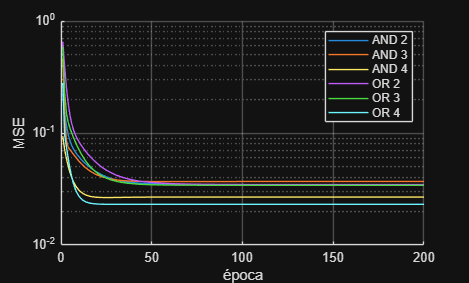

set(gca, 'YScale', 'log'); grid on; legend; xlabel('época'); ylabel('MSE')

## 13.1 Efecto de la tasa de aprendizaje en Adaline

Con una tabla de verdad la salida lineal no puede igualar exactamente los ceros y unos, así que el MSE se estabiliza en un valor positivo y no alcanza `target_mse`. Por eso el entrenamiento dura siempre `max_epochs` y lo que cambia con $\alpha$ es el MSE final y la exactitud.

alphasA = [0.001 0.01 0.05 0.1 0.5 1];
M = zeros(6, numel(alphasA));  A = M;  k = 0;
for g = 1:numel(gates)
    for n = n_inputs_list
        k = k + 1;  cfgA.n_inputs = n;
        [X, D] = generate_gate_data(n, gates{g});
        for a = 1:numel(alphasA)
            cfgA.alpha = alphasA(a);  rng(cfgA.seed);
            [W, b, mse_hist] = train_adaline(X, D, cfgA);
            M(k, a) = mse_hist(end);  A(k, a) = accuracy_of(X, D, W, b, cfgA.threshold);
        end
    end
end
nombres = matlab.lang.makeValidName(compose('alpha %g', alphasA));
MSE_final = array2table(M, 'RowNames', etiquetas, 'VariableNames', nombres)

MSE_final = 6×6 table
             alpha0_001    alpha0_01    alpha0_05    alpha0_1    alpha0_5      alpha1   
             __________    _________    _________    ________    ________    ___________

    AND 2     0.084238     0.033444     0.034625      0.03858       0.125         4946.8
    AND 3     0.066398     0.032317     0.036915     0.043945     0.15556    8.3643e+123
    AND 4     0.042952     0.022457     0.026823     0.033169     0.11292            NaN
    OR 2       0.10816     0.032871     0.034626      0.03858       0.125         4979.1
    OR 3      0.074475     0.031947     0.034106     0.037195    0.076389    8.7589e+123
    OR 4      0.047111     0.021815     0.023107     0.024604    0.040935            NaN


Exactitud = array2table(A, 'RowNames', etiquetas, 'VariableNames', nombres)

Exactitud = 6×6 table
             alpha0_001    alpha0_01    alpha0_05    alpha0_1    alpha0_5    alpha1
             __________    _________    _________    ________    ________    ______

    AND 2         50           100          100         100          75         50 
    AND 3       87.5           100          100         100        62.5       87.5 
    AND 4      93.75         93.75        93.75         100       56.25      93.75 
    OR 2          75           100          100         100          75         25 
    OR 3          75           100         87.5        87.5        87.5       12.5 
    OR 4         100         93.75        93.75       93.75       93.75       6.25 


## 13.2 Efecto del umbral de decisión

El umbral no interviene en el ajuste de los pesos, solo en la decisión final sobre la salida lineal. Se entrena una vez por compuerta y se evalúa con varios umbrales.

cfgA.alpha = 0.05;
thresholdsA = [0.3 0.5 0.7];
A = zeros(6, numel(thresholdsA));  k = 0;
for g = 1:numel(gates)
    for n = n_inputs_list
        k = k + 1;  cfgA.n_inputs = n;
        [X, D] = generate_gate_data(n, gates{g});
        rng(cfgA.seed);  [W, b] = train_adaline(X, D, cfgA);
        for t = 1:numel(thresholdsA)
            A(k, t) = accuracy_of(X, D, W, b, thresholdsA(t));
        end
    end
end
R6 = array2table(A, 'RowNames', etiquetas, 'VariableNames', matlab.lang.makeValidName(compose('umbral %g', thresholdsA)))

R6 = 6×3 table
             umbral0_3    umbral0_5    umbral0_7
             _________    _________    _________

    AND 2        100          100          100  
    AND 3        100          100         87.5  
    AND 4        100        93.75        93.75  
    OR 2         100          100          100  
    OR 3        87.5         87.5          100  
    OR 4       93.75        93.75        93.75  


## 13.3 Efecto de los pesos iniciales en Adaline

Misma prueba que en 7.4. Como el error cuadrático es convexo, se espera que los pesos finales sean los mismos sin importar de dónde se parta.

R7 = table();
for g = 1:numel(gates)
    cfgA.n_inputs = 2;
    [X, D] = generate_gate_data(2, gates{g});
    for sc = init_scales
        cfgA.init_scale = sc;
        Wf = zeros(cfgA.n_seeds, 3);  m = zeros(cfgA.n_seeds, 1);  acc = m;
        for s = 1:cfgA.n_seeds
            rng(s);
            [W, b, mse_hist] = train_adaline(X, D, cfgA);
            Wf(s, :) = [W b];  m(s) = mse_hist(end);  acc(s) = accuracy_of(X, D, W, b, cfgA.threshold);
        end
        R7 = [R7; table(gates(g), sc, mean(m), mean(acc), mean(Wf), max(Wf) - min(Wf), ...
              'VariableNames', {'Compuerta', 'Escala_inicial', 'MSE_final', 'Exactitud', 'W1_W2_b_final', 'Rango_W1_W2_b'})];
    end
end
cfgA.init_scale = 0.5;
R7

R7 = 8×6 table
    Compuerta    Escala_inicial    MSE_final    Exactitud             W1_W2_b_final                         Rango_W1_W2_b             
    _________    ______________    _________    _________    _______________________________    ______________________________________

     {'AND'}             0         0.034625        100       0.52576     0.51259    -0.26245             0             0             0
     {'AND'}         0.001         0.034625        100       0.52576     0.51259    -0.26245    2.0443e-06    2.2176e-06    2.6902e-06
     {'AND'}           0.5         0.034625        100       0.52579     0.51262    -0.26248     0.0010221     0.0011088     0.0013451
     {'AND'}             5         0.034628        100       0.52602     0.51284    -0.26276      0.010221      0.011088      0.013451
     {'OR' }             0         0.034627        100       0.47341     0.48656     0.26351             0             0             0
     {'OR' }         0.001         0.03

## 13.4 Control negativo, la compuerta XOR

La XOR no es linealmente separable, así que ninguno de los dos modelos debe resolverla. Se usa como control para verificar que el resto de los resultados no proviene de un error de implementación.

[X, ~] = generate_gate_data(2, 'AND');
D_xor = double(xor(X(:, 1), X(:, 2)));
cfg.n_inputs = 2;  rng(cfg.seed);
[Wp, bp, ep_xor] = train_perceptron(X, D_xor, cfg);
cfgA.n_inputs = 2;  rng(cfgA.seed);
[Wa, ba, mse_xor] = train_adaline(X, D_xor, cfgA);
XOR = table({'Perceptrón'; 'Adaline'}, [ep_xor; numel(mse_xor)], [NaN; mse_xor(end)], ...
    [accuracy_of(X, D_xor, Wp, bp, cfg.threshold); accuracy_of(X, D_xor, Wa, ba, cfgA.threshold)], ...
    'VariableNames', {'Modelo', 'Epocas', 'MSE_final', 'Exactitud'})

XOR = 2×4 table
        Modelo        Epocas    MSE_final    Exactitud
    ______________    ______    _________    _________

    {'Perceptrón'}     100          NaN         25    
    {'Adaline'   }     200       0.1385         25    


## 13.5 Dinámica del error, Perceptrón frente a Adaline

El Perceptrón cuenta errores enteros por época y se detiene en la primera época sin errores; el Adaline sigue un descenso continuo sobre el MSE. Para reconstruir la trayectoria del Perceptrón se entrena con un tope de épocas creciente, que con semilla fija reproduce la misma secuencia de correcciones.

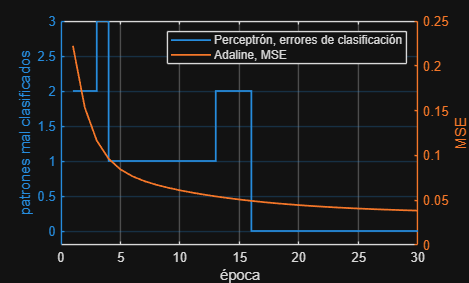

[X, D] = generate_gate_data(2, 'AND');
n_ep = 30;
errores = zeros(n_ep, 1);
for k = 1:n_ep
    cfg.max_epochs = k;  rng(cfg.seed);
    [W, b] = train_perceptron(X, D, cfg);
    errores(k) = sum(step_activation(X * W' + b, cfg.threshold) ~= D);
end
cfg.max_epochs = 100;
cfgA.max_epochs = n_ep;  rng(cfgA.seed);
[~, ~, mse_and] = train_adaline(X, D, cfgA);
cfgA.max_epochs = 200;

figure
yyaxis left;  stairs(errores, 'LineWidth', 1.3); ylabel('patrones mal clasificados'); ylim([-0.2 3])
yyaxis right; plot(mse_and, 'LineWidth', 1.3); ylabel('MSE')
xlabel('época'); grid on; legend('Perceptrón, errores de clasificación', 'Adaline, MSE')

## 14. Aplicación de Adaline a datos reales — `data_banknote_authentication.txt`

**Qué se espera en esta sección:** al igual que en la Sección 9, entrenar y evaluar Adaline sobre las particiones 60-40, 70-30, 80-20 y 90-10, y comparar sus resultados contra los del Perceptrón (Parte A) y, más adelante, contra el MLP del Taller 2.

Se corre con las entradas tal como vienen y escaladas al rango 0 a 1, porque en la Regla Delta la corrección es proporcional a la entrada y las cuatro variables de este dataset están en escalas muy distintas.

alphasA_bank = [1e-4 1e-3 1e-2 5e-2];
R8 = table();
for nz = [false true]
    cfgA.normalize = nz;
    for r = proporciones
        [Xtr, Dtr, Xte, Dte] = split_dataset(X_bank, D_bank, r, cfgA.seed);
        if cfgA.normalize, [Xtr, Xte] = scale_minmax(Xtr, Xte); end
        cfgA.n_inputs = size(Xtr, 2);
        for a = alphasA_bank
            cfgA.alpha = a;  rng(cfgA.seed);
            [W, b, mse_hist] = train_adaline(Xtr, Dtr, cfgA);
            R8 = [R8; table(nz, r, a, numel(mse_hist), mse_hist(end), accuracy_of(Xtr, Dtr, W, b, cfgA.threshold), accuracy_of(Xte, Dte, W, b, cfgA.threshold), ...
                  'VariableNames', {'Escalado', 'Proporcion', 'Alpha', 'Epocas', 'MSE_final', 'Exact_entrenamiento', 'Exact_prueba'})];
        end
    end
end
R8

R8 = 32×7 table
    Escalado    Proporcion    Alpha     Epocas    MSE_final    Exact_entrenamiento    Exact_prueba
    ________    __________    ______    ______    _________    ___________________    ____________

     false         0.6        0.0001     200      0.016301            97.57              96.539   
     false         0.6         0.001     200      0.017073           98.542               97.45   
     false         0.6          0.01     200      0.033378            95.99              96.357   
     false         0.6          0.05     200           NaN             54.8              56.648   
     false         0.7        0.0001     200      0.015908           98.021              96.117   
     false         0.7         0.001     200      0.016645           97.708              95.874   
     false         0.7          0.01     200      0.040168           77.604               72.33   
     false         0.7          0.05     200           NaN           54.375              58.

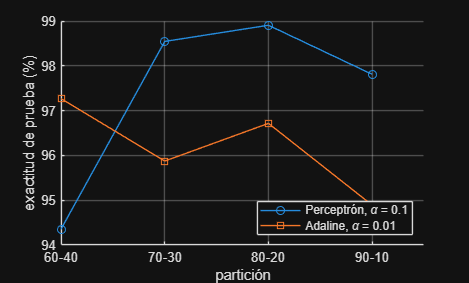


figure; hold on
plot(proporciones, R5.Exact_prueba(R5.Alpha == 0.1), '-o', 'DisplayName', 'Perceptrón, \alpha = 0.1')
plot(proporciones, R8.Exact_prueba(R8.Escalado & R8.Alpha == 0.01), '-s', 'DisplayName', 'Adaline, \alpha = 0.01')
xticks(proporciones); xticklabels({'60-40', '70-30', '80-20', '90-10'})
xlabel('partición'); ylabel('exactitud de prueba (%)'); grid on; legend('Location', 'southeast')

## 14.1 Matriz de confusión en la partición 70-30

La exactitud sola no dice de qué lado se equivoca el modelo. Se reportan los cuatro conteos sobre el conjunto de prueba con las entradas escaladas.

[Xtr, Dtr, Xte, Dte] = split_dataset(X_bank, D_bank, 0.7, cfg.seed);
[Xtr, Xte] = scale_minmax(Xtr, Xte);
cfg.n_inputs = size(Xtr, 2);  cfg.alpha = 0.1;  rng(cfg.seed);
[Wp, bp] = train_perceptron(Xtr, Dtr, cfg);
cfgA.n_inputs = size(Xtr, 2);  cfgA.alpha = 0.01;  rng(cfgA.seed);
[Wa, ba] = train_adaline(Xtr, Dtr, cfgA);
Yp = step_activation(Xte * Wp' + bp, cfg.threshold);
Ya = step_activation(Xte * Wa' + ba, cfgA.threshold);
Confusion = table([sum(Yp == 0 & Dte == 0); sum(Ya == 0 & Dte == 0)], ...
                  [sum(Yp == 1 & Dte == 0); sum(Ya == 1 & Dte == 0)], ...
                  [sum(Yp == 0 & Dte == 1); sum(Ya == 0 & Dte == 1)], ...
                  [sum(Yp == 1 & Dte == 1); sum(Ya == 1 & Dte == 1)], ...
    'RowNames', {'Perceptrón', 'Adaline'}, 'VariableNames', {'TN', 'FP', 'FN', 'TP'})

Confusion = 2×4 table
                  TN     FP    FN    TP 
                  ___    __    __    ___

    Perceptrón    236     4    2     170
    Adaline       223    17    0     172


Pesos_bank = table([Wp'; bp], [Wa'; ba], 'RowNames', [vars_bank, {'sesgo'}], ...
    'VariableNames', {'Perceptron', 'Adaline'})

Pesos_bank = 5×2 table
                 Perceptron    Adaline 
                 __________    ________

    varianza       -7.1235      -1.9602
    asimetria      -7.5406      -2.0901
    curtosis       -7.8253      -2.3748
    entropia      -0.11022     -0.01824
    sesgo           10.577       3.4608


## Funciones locales

MATLAB permite definir funciones locales al final de un script. No cambie los nombres ni los argumentos de entrada/salida.

function [X, D] = generate_gate_data(n_inputs, gate)
    % Genera la tabla de verdad completa (2^n_inputs patrones) para una
    % compuerta AND u OR de n_inputs entradas. Ya está completa.
    n_patterns = 2^n_inputs;
    X = zeros(n_patterns, n_inputs);
    for p = 0:n_patterns-1
        X(p+1, :) = bitget(p, n_inputs:-1:1);
    end

    switch upper(gate)
        case 'AND'
            D = double(all(X, 2));
        case 'OR'
            D = double(any(X, 2));
        otherwise
            error('Compuerta no reconocida: %s', gate);
    end
end

function [W, b] = init_perceptron(cfg)
    % Inicializa pesos y sesgo con valores aleatorios pequeños.
    W = randn(1, cfg.n_inputs) * cfg.init_scale;
    b = randn(1) * cfg.init_scale;
end

function y = step_activation(net, threshold)
    % Función escalón: 1 si net >= threshold, 0 en caso contrario.
    y = double(net >= threshold);
end

function delta = compute_delta(cfg, d, y, x)
    % Calcula el incremento de pesos Delta_W según la regla seleccionada
    % en cfg.learning_rule. `x` es un patrón (vector fila), `d` la
    % salida deseada y `y` la salida actual del Perceptrón (ya
    % escalonada).
    switch cfg.learning_rule
        case 'hebb'
            delta = d * x;
        case 'perceptron'
            delta = (d - y) * x;
        case 'perceptron_alpha'
            delta = cfg.alpha * (d - y) * x;
        otherwise
            error('Regla de aprendizaje no reconocida: %s', cfg.learning_rule);
    end
end

function [W, b, epochs_to_converge] = train_perceptron(X, D, cfg)
    [W, b] = init_perceptron(cfg);
    epochs_to_converge = cfg.max_epochs;

    for epoch = 1:cfg.max_epochs
        n_errors = 0;
        for p = 1:size(X, 1)
            x = X(p, :);
            d = D(p);

            net = W * x' + b;
            y = step_activation(net, cfg.threshold);

            if y ~= d
                n_errors = n_errors + 1;
            end

            delta = compute_delta(cfg, d, y, x);
            W = W + delta;
            b = b + (d - y);   % el sesgo se ajusta como un peso más (entrada constante = 1)
        end

        if n_errors == 0
            epochs_to_converge = epoch;
            break;
        end
    end
end

function [W, b] = init_adaline(cfg)
    % Igual que init_perceptron, pero para Adaline.
    W = randn(1, cfg.n_inputs) * cfg.init_scale;
    b = randn(1) * cfg.init_scale;
end

function [W, b, mse_hist] = train_adaline(X, D, cfgA)
    [W, b] = init_adaline(cfgA);
    mse_hist = zeros(cfgA.max_epochs, 1);

    for epoch = 1:cfgA.max_epochs
        epoch_error = 0;
        for p = 1:size(X, 1)
            x = X(p, :);
            d = D(p);

            net = W * x' + b;   % salida LINEAL (sin escalón)
            y = net;

            delta = cfgA.alpha * (d - y) * x;
            W = W + delta;
            b = b + cfgA.alpha * (d - y);

            epoch_error = epoch_error + 0.5 * (d - y)^2;
        end

        mse_hist(epoch) = epoch_error / size(X, 1);
        if mse_hist(epoch) <= cfgA.target_mse
            mse_hist = mse_hist(1:epoch);
            break;
        end
    end
end

function [Xtr, Dtr, Xte, Dte] = split_dataset(X, D, train_ratio, seed)
    % Divide (X, D) en un subconjunto de entrenamiento y uno de prueba,
    % respetando la proporción train_ratio (p. ej. 0.7 = 70% entrenamiento).
    rng(seed);
    n = size(X, 1);
    idx = randperm(n);
    n_train = round(train_ratio * n);
    idx_train = idx(1:n_train);
    idx_test  = idx(n_train+1:end);
    Xtr = X(idx_train, :); Dtr = D(idx_train, :);
    Xte = X(idx_test, :);  Dte = D(idx_test, :);
end

function acc = accuracy_of(X, D, W, b, threshold)
    % Exactitud en porcentaje de la neurona (W, b) con escalón en threshold.
    Y = step_activation(X * W' + b, threshold);
    acc = mean(Y == D) * 100;
end

function [Xtr, Xte] = scale_minmax(Xtr, Xte)
    % Escala cada columna al rango 0 a 1 con los mínimos y máximos del entrenamiento.
    mn = min(Xtr);  mx = max(Xtr);
    Xtr = (Xtr - mn) ./ (mx - mn);
    Xte = (Xte - mn) ./ (mx - mn);
end